De La Salle University

Electronics and Computer Engineering Department

Course : LBYEC4A/LBYCPA4 SECTION : Submitted by : Jared Ong Submitted to : Dr. Edwin Sybingco

Exercise 4 : FIR Filter Note: Check the instructions given in canvas

## Task 1

Specify the order of the window

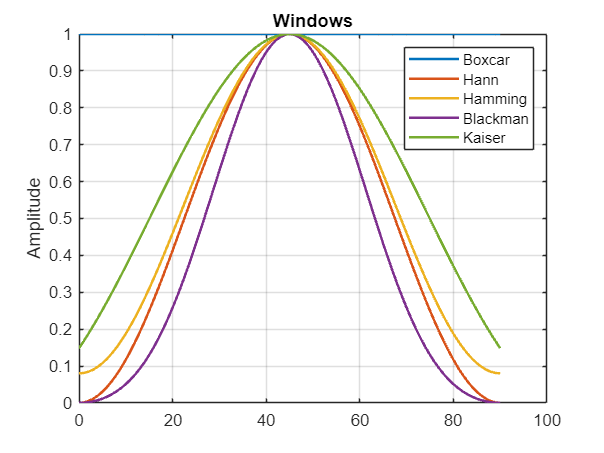

M=90;
% Generate the time index
n=0:M;

% Place your code here to generate w
w = zeros(M+1,5);
w(:,1) = rectwin(M+1);
w(:,2) = hann(M+1);
w(:,3) = hamming(M+1);
w(:,4) = blackman(M+1);
w(:,5) = kaiser(M+1, 3.3953);

% Place your code here to calculate W
W = zeros(512,5);
[W(:,1), omega] = freqz(w(:,1), 1, 512);
for k = 2:5
    W(:,k) = freqz(w(:,k), 1, omega);
end

% Place your code here to create the visualization of figure 1
figure(1);
plot(n, w(:,1), n, w(:,2), n, w(:,3), n, w(:,4), n, w(:,5), 'LineWidth', 1.5);
legend('Boxcar', 'Hann', 'Hamming', 'Blackman', 'Kaiser');

ylabel('Amplitude');
title('Windows');
grid on;

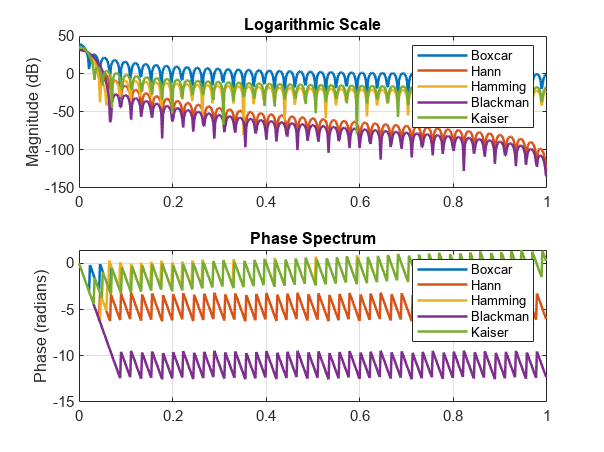


% Place your code here to create the visualization of figure 2
figure(2);
subplot(2,1,1);
plot(omega/pi, 20*log10(abs(W(:,1)) + eps), ...
     omega/pi, 20*log10(abs(W(:,2)) + eps), ...
     omega/pi, 20*log10(abs(W(:,3)) + eps), ...
     omega/pi, 20*log10(abs(W(:,4)) + eps), ...
     omega/pi, 20*log10(abs(W(:,5)) + eps), 'LineWidth', 1.5);
legend('Boxcar', 'Hann', 'Hamming', 'Blackman', 'Kaiser');

ylabel('Magnitude (dB)');
title('Logarithmic Scale');
grid on;

subplot(2,1,2);
plot(omega/pi, unwrap(angle(W(:,1))), ...
     omega/pi, unwrap(angle(W(:,2))), ...
     omega/pi, unwrap(angle(W(:,3))), ...
     omega/pi, unwrap(angle(W(:,4))), ...
     omega/pi, unwrap(angle(W(:,5))), 'LineWidth', 1.5);
legend('Boxcar', 'Hann', 'Hamming', 'Blackman', 'Kaiser');

ylabel('Phase (radians)');
title('Phase Spectrum');
grid on;

## Task 2

specify the parameters of the function fir2 based on the given specifications

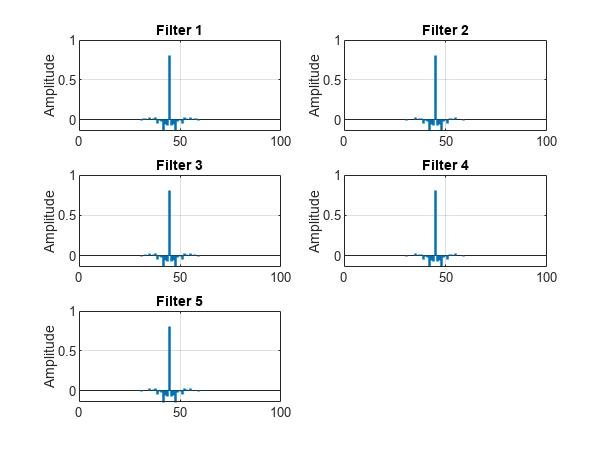

F = [0, 0.1, 0.2, 0.5, 0.7, 0.8, 1];
A = [0.2, 0.2, 1, 1, 0.5, 1, 1];

% Place your code here to design the five filters and store it in matrix b1
b1 = zeros(5, M+1);
for k = 1:5
    b1(k,:) = fir2(M, F, A, w(:,k));
end

% Place your code here to determine the half frequency frequency representation of the five filters with 512 frequency points. Store the result in the matrix H1. The expected size of H1 is 512 x 5
H1 = zeros(512,5);
[H1(:,1), omega] = freqz(b1(1,:), 1, 512);
for k = 2:5
    H1(:,k) = freqz(b1(k,:), 1, omega);
end

% Place your code here to create the visualization of figure 3
figure(3);
for k = 1:5
    subplot(3,2,k);
    stem(0:M, b1(k,:), 'Marker', 'none', 'LineWidth', 1.5);
    title(['Filter ', num2str(k)]);
    
    ylabel('Amplitude');
    grid on;
end

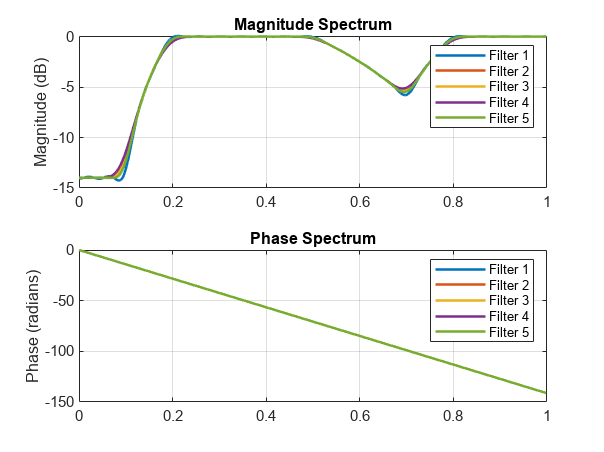


% Place your code here to create the visualization of figure 4
figure(4);
subplot(2,1,1);
plot(omega/pi, 20*log10(abs(H1(:,1)) + eps), ...
     omega/pi, 20*log10(abs(H1(:,2)) + eps), ...
     omega/pi, 20*log10(abs(H1(:,3)) + eps), ...
     omega/pi, 20*log10(abs(H1(:,4)) + eps), ...
     omega/pi, 20*log10(abs(H1(:,5)) + eps), 'LineWidth', 1.5);
legend('Filter 1', 'Filter 2', 'Filter 3', 'Filter 4', 'Filter 5');

ylabel('Magnitude (dB)');
title('Magnitude Spectrum');
grid on;

subplot(2,1,2);
plot(omega/pi, unwrap(angle(H1(:,1))), ...
     omega/pi, unwrap(angle(H1(:,2))), ...
     omega/pi, unwrap(angle(H1(:,3))), ...
     omega/pi, unwrap(angle(H1(:,4))), ...
     omega/pi, unwrap(angle(H1(:,5))), 'LineWidth', 1.5);
legend('Filter 1', 'Filter 2', 'Filter 3', 'Filter 4', 'Filter 5');

ylabel('Phase (radians)');
title('Phase Spectrum');
grid on;

## Task 3

Place your code here to design the lowpass filter

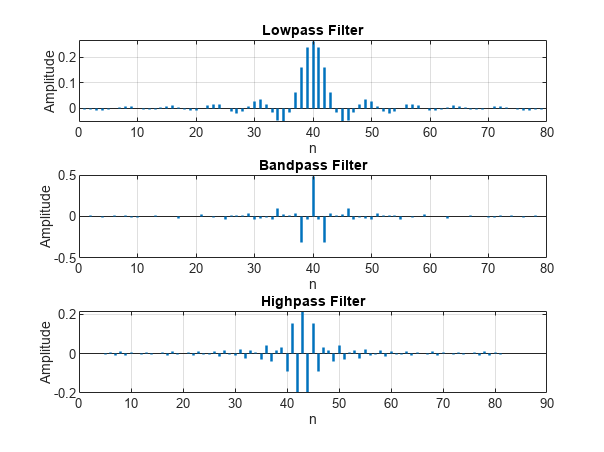

delta1 = 0.0575; delta2 = 0.0009;
Wp = 0.25 * pi; Ws = 0.3 * pi;
[N_lp, Fo, Ao, W] = firpmord([Wp/pi, Ws/pi], [1, 0], [delta1, delta2]);
N_lp = N_lp + rem(N_lp, 2);
b_lp = firpm(N_lp, Fo, Ao, W);

% Place your code here to design the bandpass filter
Wp = [0.3, 0.75] * pi; Ws = [0.25, 0.8] * pi;
[N_bp, Fo, Ao, W] = firpmord([Ws(1)/pi, Wp(1)/pi, Wp(2)/pi, Ws(2)/pi], [0, 1, 0], [delta2, delta1, delta2]);
N_bp = N_bp + rem(N_bp, 2);
b_bp = firpm(N_bp, Fo, Ao, W);

% place your code here to design the highpass filter
Wp = 0.8 * pi; Ws = 0.75 * pi;
[N_hp, Fo, Ao, W] = firpmord([Ws/pi, Wp/pi], [0, 1], [delta2, delta1]);
N_hp = N_hp + rem(N_hp, 2);
b_hp = firpm(N_hp, Fo, Ao, W);

% Place your code here to determine the frequency response of the three filters
b2 = zeros(3, max([N_lp, N_bp, N_hp]) + 1);
b2(1,1:N_lp+1) = b_lp;
b2(2,1:N_bp+1) = b_bp;
b2(3,1:N_hp+1) = b_hp;

H2 = zeros(512, 3);
[H2(:,1), omega] = freqz(b2(1,1:N_lp+1), 1, 512);
[H2(:,2), ~] = freqz(b2(2,1:N_bp+1), 1, omega);
[H2(:,3), ~] = freqz(b2(3,1:N_hp+1), 1, omega);

% Place your code here to create the visualization (impulse response) of figure 5
figure(5);
subplot(3,1,1); stem(0:N_lp, b_lp, 'Marker', 'none', 'LineWidth', 1.5);
title('Lowpass Filter'); xlabel('n'); ylabel('Amplitude'); grid on;
subplot(3,1,2); stem(0:N_bp, b_bp, 'Marker', 'none', 'LineWidth', 1.5);
title('Bandpass Filter'); xlabel('n'); ylabel('Amplitude'); grid on;
subplot(3,1,3); stem(0:N_hp, b_hp, 'Marker', 'none', 'LineWidth', 1.5);
title('Highpass Filter'); xlabel('n'); ylabel('Amplitude'); grid on;

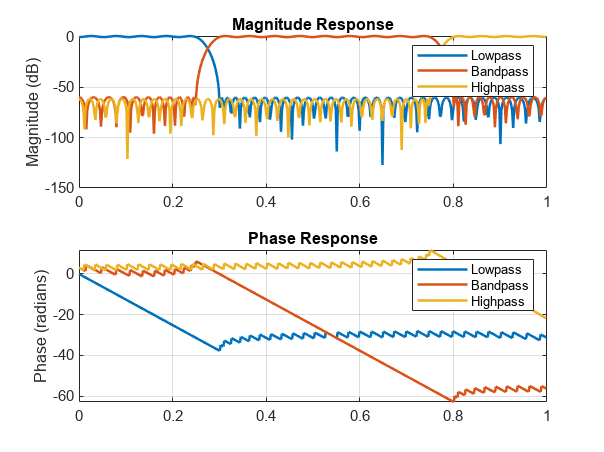


% Place your code here to create the visualization (magnitude and phase spectrum of figure 6
figure(6);
subplot(2,1,1);
plot(omega/pi, 20*log10(abs(H2(:,1)) + eps), ...
     omega/pi, 20*log10(abs(H2(:,2)) + eps), ...
     omega/pi, 20*log10(abs(H2(:,3)) + eps), 'LineWidth', 1.5);
legend('Lowpass', 'Bandpass', 'Highpass');

ylabel('Magnitude (dB)');
title('Magnitude Response');
grid on;

subplot(2,1,2);
plot(omega/pi, unwrap(angle(H2(:,1))), ...
     omega/pi, unwrap(angle(H2(:,2))), ...
     omega/pi, unwrap(angle(H2(:,3))), 'LineWidth', 1.5);
legend('Lowpass', 'Bandpass', 'Highpass');

ylabel('Phase (radians)');
title('Phase Response');
grid on;

## 4

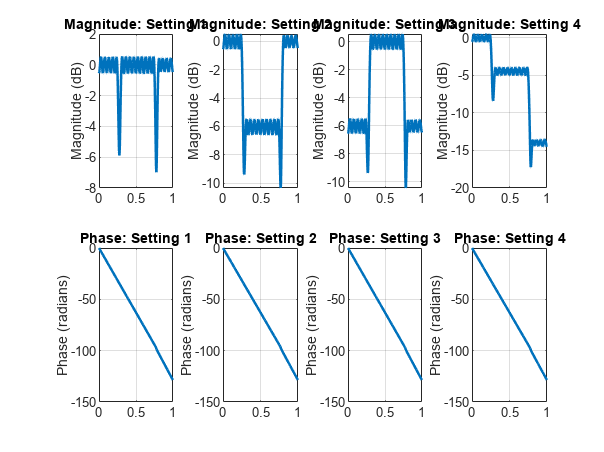

alpha = [1 1 1; 1 0.5 1; 0.5 1 0.5; 1 0.6 0.2];
% Place your code here to compute for H3
H3 = zeros(512,4);
for i = 1:4
    H3(:,i) = alpha(i,1)*H2(:,1) + alpha(i,2)*H2(:,2) + alpha(i,3)*H2(:,3);
end

% Place your code here to create the visualization (magnitude and phase spectrum of figure 7
figure(7);
for i = 1:4
    subplot(2,4,i);
    plot(omega/pi, 20*log10(abs(H3(:,i)) + eps), 'LineWidth', 1.5);
    
    ylabel('Magnitude (dB)');
    title(['Magnitude: Setting ', num2str(i)]);
    grid on;
    
    subplot(2,4,i+4);
    plot(omega/pi, unwrap(angle(H3(:,i))), 'LineWidth', 1.5);
    
    ylabel('Phase (radians)');
    title(['Phase: Setting ', num2str(i)]);
    grid on;
end

## 5

Read the audio file and store it in the first column of y

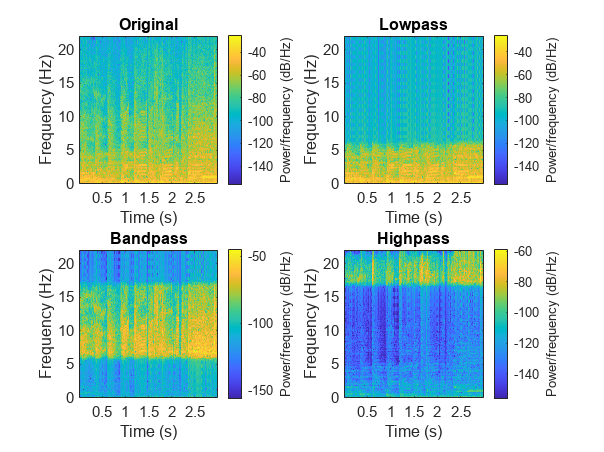

[y(:,1),Fs] = audioread('RollingInTheDeep.wav');

% Place your code here to generate y1, y2, and y3 and store them in the 2nd, 3rd, and 4th column of y
y(:,2) = filter(b2(1,1:N_lp+1), 1, y(:,1));
y(:,3) = filter(b2(2,1:N_bp+1), 1, y(:,1));
y(:,4) = filter(b2(3,1:N_hp+1), 1, y(:,1));

% Place your code here to calculate the spectrogram of y and store them in the three-dimensional matrix S
S = zeros(257, 1032, 4);
window = kaiser(256, 3.3953);
noverlap = 128;
nfft = 512;
for k = 1:4
    [S(:,:,k), ~, ~] = spectrogram(y(:,k), window, noverlap, nfft, Fs);
end

% Place your code here to create the visualization (spectrogram) of figure 8
figure(8);
for i = 1:4
    subplot(2,2,i);
    spectrogram(y(:,i), window, noverlap, nfft, Fs, 'yaxis');
    switch i
        case 1
            title('Original');
        case 2
            title('Lowpass');
        case 3
            title('Bandpass');
        case 4
            title('Highpass');
    end
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
end